%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CODE CHALLENGE 5 - Template Script
%
% The purpose of this challenge is to predict whether or not the Boulder
% Reservior will have to close due to a major leak.
%
% To complete the challenge, execute the following steps:
% Part 1:
% 1) Read in the data file
% 2) Set values to any constants
% 3) Perform a trapazoid integration on the data w/r.t. x
% 4) Perform a simpson's 1/3 integration on the data w/r.t. x
% 5) Display which volume measurement is more accurate and why
%
% Part 2:
% 1) Define which delta t will be used in the Euler integration
% 2) Set values to any constants and initial conditions
% 3) Propagate h with t using Euler integration
% 4) Repeat steps 1-4 with different delta t values
% 5) Display which delta t gives a more accurate result and why.
% 
%
% NOTE: DO NOT change any variable names already present in the code.
% 
% Upload your team's script to Gradescope to complete the challenge.
% 
% NAME YOUR FILE AS Challenge5_Sec{section number}_Group{group breakout #}.m 
% ***Section numbers are 1 or 2*** 
% EX File Name: Challenge5_Sec1_Group15.m 
%
%
% 1) Suphakan Sukwong
% 2) John Glezen
% 3) Reid Godbey
% 4) Tristan Workman
% 5) Brendan Sheets
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Housekeeping

don't "clear variables", it makes things easier to grade

close all;   % Close all open figure windows
clc;         % Clear the command window

## Part 1

## Set up

data = readtable("depth_data.csv") % read in .csv

data = 31×2 table
      x         d   
    ______    ______

         0         0
    223.82     5.126
    447.64    9.6481
    671.46    13.478
    895.29    16.552
    1119.1    18.844
    1342.9    20.369
    1566.8    21.183
    1790.6    21.381
    2014.4    21.089
    2238.2     20.45
      2462    19.614
    2685.9     18.72
    2909.7    17.886
    3133.5    17.196
    3357.3    16.696


x = data.x; % [ft]
d = data.d; % [ft]
L = 4836; % length of reservior [ft]

## Trapazoid - Calculate Volume

n = length(x) - 1;
dx = 223.8215;
Area = 0;
for i=1:n % summation for repeating values
    Area = Area + (dx * d(i));
end
Area = Area + (dx./2)*(d(1)+d(n+1))

Area = 9.5403e+04

comparison = trapz(x,d) % checking accuracy

comparison = 9.5403e+04

Vol_trap = Area * L; % [ft^3]

## Simpson 1/3 - Calculate Volume

sum1 = 0;
for i=2:(n/2) % first summation for odd repeating values
    sum1 = sum1 + d(2*i-1);
end
sum2 = 0;
for i=1:(n/2) % second summation for even repeating values
    sum2 = sum2 + d(2*i);
end
Area_S = dx/3 * (d(1) + d(n+1) + (2 * sum1) + (4 * sum2)) % area

Area_S = 9.5536e+04

V_simp = Area_S * L % [ft^3] 

V_simp = 4.6201e+08

The simpsons rule calculation is much more accurate.

## Part 2

## Set up

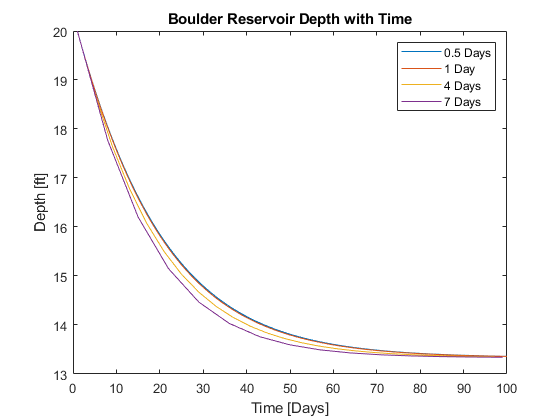

del_t = [0.5 1 4 7]; % various delta t values to test [days]
% time vector with the 4 provided delta t's
figure(1) % create figure

h0 = 20; % initial depth
alpha = 1.5 * 10^6; % relating volume out per day to depth [ft^2/day]
dV_in = 2 * 10^7; % volume in rate per day

for j = 1:4 % for plotting the 4 delta t's
    t = 1:del_t(j):100; % allocate time vector [days]
    h = zeros(length(t),1); % allocate depth vector [ft]
    h(1)= h0; % set initial value in h vector
    for i = 1:(length(t)-1) % Euler method
        dhdt = get_dhdt(h(i),L,alpha,dV_in); % get dh/dt at this depth
        h(i+1) = h(i) + dhdt*del_t(j); %compute next depth value
    end
    plot(t,h)
    hold on
end
legend("0.5 Days","1 Day","4 Days","7 Days")
title("Boulder Reservoir Depth with Time")
xlabel("Time [Days]")
ylabel("Depth [ft]")


% plot results

% labels for plot